clc
clear
close all

## Step 1: Import cleaned dataset from spreadsheet

% Script for importing open-door data from spreadsheet:

M=readmatrix('Input Files/door opening-cleaned.xlsx','Range','A3');
Time=M(:,1);
Temp=M(:,2);

save('plantoutput.mat','Temp','Time')
LastTimeStamp=Time(end);
sim("ReadTimeSeries.slx");
open_system('ReadTimeSeries/Scope')
pause(3)

Rate of temperature increase (deg C per minute) by convection when door is opened

ODTRR=input('Input the Open-Door Temperature-Rise Rate (deg C/unit time)');
if isempty(ODTRR)==1
    ODTRR=readmatrix('Input Files/SysIDSetupData.xlsx',"Range",'C7:C7');
end


% Script for importing closed-door data from spreadsheet:
M=readmatrix('Input Files/No door openings-cleaned.xlsx','Range','A3');
Time=M(:,1);
Temp=M(:,2);

save('plantoutput.mat','Temp','Time')
LastTimeStamp=Time(end);
sim("ReadTimeSeries.slx");
open_system('ReadTimeSeries/Scope')

Rate of temperature increase (deg C per minute) by conduction

CDTRR=input('Input the Closed-Door Temperature-Rise Rate (deg C/unit time)');
if isempty(CDTRR)==1
    CDTRR=readmatrix('Input Files/SysIDSetupData.xlsx','Sheet',"Parameters","Range",'C8:C8');
end

Controller sample time

CST=input('Input the Controller Sampling Time');
if isempty(CST)==1
    CST=readmatrix('Input Files/SysIDSetupData.xlsx','Sheet',"Parameters","Range",'C9:C9');
end

## Step 2: Identify the defining features of the system

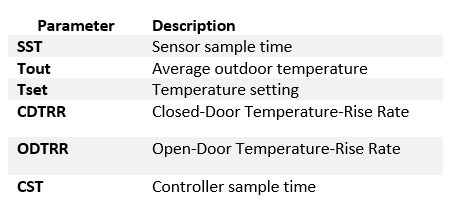

### Parameters known prior to data inspection

Thermostat set temperature

Tset=readmatrix('Input Files/SysIDSetupData.xlsx','Sheet',"Parameters","Range",'C3:C3');

Sensor sample time

SST=readmatrix('Input Files/SysIDSetupData.xlsx','Sheet',"Parameters","Range",'C5:C5');

Average Outdoor Temperature

Tout=readmatrix('Input Files/SysIDSetupData.xlsx','Sheet',"Parameters","Range",'C4:C4');

% Save parameters to a matlab file to be loaded later when model is used
% for prediction

save('plantparameters.mat','Tset','SST','CST','Tout','ODTRR',"CDTRR")

## Step 3: System Identification Process

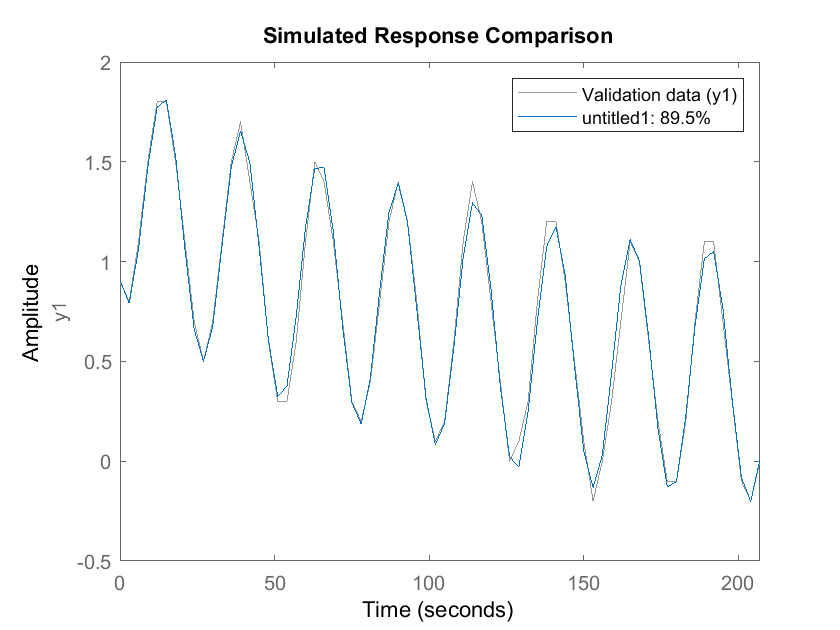

% Create an iddata object consisting of an input signal (predicted error signal) and an output
% signal (experimental temperature time series)

out=sim("SysIDPrep_v17.slx");

% Determine the order of the state space model by specifying argument nx as a range from 1:10

nx = 1:10;

% An automatically generated plot shows the Hankel singular values for models of the orders specified by nx.
% States with relatively small Hankel singular values can be safely discarded. (Red is usually the recommended choice for model reduction).
% Select the model order in the Chosen Order list and click Apply.

% The predicted model must be stable
opt = ssestOptions('EnforceStability',1);

sys = ssest(out.data,nx,opt);

compare(out.data,sys)

save('plantmodel.mat', 'sys')